# Problem 8 - Input Constraint MPC

clear all; close all; clc;
% addpath('Functions\')
% addpath('Functions\Realization\')

# Minimum vs Non-minimum phase

%% Minimum Phase System
gamma1 = 0.6; gamma2 = 0.75;

%% Non-Minimum Phase System
% gamma1 = 0.45; gamma2 = 0.4;

%% Unstable case
% gamma1 = 0.5; gamma2 = 0.5;

# Parameter constants for the system

[p,a,A,g,rho] = get_parameters(gamma1,gamma2); 

# Simulation time

t0 = 0.0;           % [s] Initial time
t_f = 20*60;        % [s] Final time
% t_f = 20*100;     % [s] Final time
Ts = 4;             % [s] Sample time
t = [t0:Ts:t_f]';   % [s] Sample instants
Nsim = length(t);

# Inital values for Liquid mass

m10 = 0.0; % [g] Liquid mass in tank 1 at time t0
m20 = 0.0; % [g] Liquid mass in tank 2 at time t0
m30 = 0.0; % [g] Liquid mass in tank 3 at time t0
m40 = 0.0; % [g] Liquid mass in tank 4 at time t0
x0 = [m10; m20; m30; m40];

# Flow rates from pumps

F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 0.0; % Unknown stochastic variables (normal distributed) 
F4 = 0.0; % Unknown stochastic variables (normal distributed)

# Initial values for control inputs and stochastic variables

u = [F1 ; F2];
d = [F3(:,1) ; F4(:,1)];
u_rep = [repmat(F1,1,Nsim); repmat(F2,1,Nsim)];
d_rep = [repmat(F3,1,Nsim); repmat(F4,1,Nsim)];

u1 = 1.10*u_rep; % 10%, control signal 
u2 = 1.25*u_rep; % 25%, control signal  
u3 = 1.50*u_rep; % 50%, control signal

# Steady states and initial guess of steady state for non-linear variables

% Steady states
xs0 = 5000*ones(4,1);       % Initial guess of steady state

us  = u;
xs  = fsolve(@ModifiedFourTankSystemWrap, xs0, [], u ,d , p); % Steady State


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ys  = FourTankSystemSensor(xs,p); % Get outputs
zs  = FourTankSystemOutput(xs,p); % Get measured outputs

# Linearize the model


$$x_{k+1} = A_c x_k + B_c u_k + E_c (d_k + w_k) \\
y_{k+1} = C_c x_k + v_k \\
z_{k+1} = C_c x_k$$


[Ac,Bc,Cc,Cz,Ec] = get_linearizedModel(p,xs)

Ac =    -0.0152         0    0.0518         0
         0   -0.0113         0    0.0324
         0         0   -0.0518         0
         0         0         0   -0.0324


Bc =     0.6000         0
         0    0.7500
         0    0.2500
    0.4000         0


Cc =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Cz =     0.0026         0         0         0
         0    0.0026         0         0


Ec =      0     0
     0     0
     1     0
     0     1


# Discretize the model

[Ad,Bd]=c2dzoh(Ac,Bc,Ts);
[~,Ed]=c2dzoh(Ac,Ec,Ts);
Cd = Cc;
Cdz = Cz;

# Noise for the model

This noise is not the one for the system (the real plant)

% Noise variance
Qe = diag([5^2 5^2]);           % Process noise
Rv = diag([2^2 2^2 2^2 2^2]);   % Measurement noise

% Generate noise vector
qe = chol(Qe,'lower');   W  = qe*randn(2,Nsim);     % Process noise 
rv = chol(Rv,'lower');   V  = rv*randn(4,Nsim);     % Measurement noise

% New noise W_bar (used to get noise matrix with 4 rows instead of 2 rows)
Qe_bar = diag(Ed.^2*Qe*[1; 1]);
qe_bar = chol(Qe_bar,'lower');
W_bar  = qe_bar*randn(4,Nsim); % New process noise

Gd_bar = diag([1;1;1;1]);    % Noise matrix for W_bar (not really needed)

# Noise for the system

This noise is used for the real plant

% Noise variance
Qe_system = diag([5^2 5^2]);           % Process noise
Rv_system = diag([2^2 2^2 2^2 2^2]);   % Measurement noise

% Generate noise vector
qe_system = chol(Qe_system,'lower');   W_system  = qe_system*randn(2,Nsim);     % Process noise 
rv_system = chol(Rv_system,'lower');   V_system  = rv_system*randn(4,Nsim);     % Measurement noise

% New noise W_bar (used to get noise matrix with 4 rows instead of 2 rows)
Qe_bar_sys = diag(Ed.^2*Qe_system*[1; 1]);
qe_bar_sys = chol(Qe_bar_sys,'lower');
W_bar_sys  = qe_bar*randn(4,Nsim); % New process noise

Gd_bar_sys = diag([1;1;1;1]);    % Noise matrix for W_bar (not really needed)

# MPC Input Constraints

Nph = 70; % Prediction Horizon

% Output vs. Input dimensions
nz = size(Cdz,1); % Number of controllable outputs
nu = size(Bd,2);  % Number of inputs

% Weight Matrices
value1 = 20^3; % Original value, Test 1
value2 = 1;   % Original value, Test 1
% value1 = 20^3; % Test 2
% value2 = 0.4;   % Test 2
% value1 = 7^3; % Test 3
% value2 = 1;   % Test 3

% Reference weight matrix
Qz_weight_ref = eye(nz,nz);
Qz_weight_ref = value1*Qz_weight_ref;
% Control input weight matrix
Qdu_weight_input = eye(nu,nu);
Qdu_weight_input = value2*Qdu_weight_input;

%%%%% MPC Matrices
Gamma = get_Gamma(Nph,Ad,Bd,Cdz); 
Phix  = get_Phix(Ad,Cdz,Nph);
Phiw  = get_Phiw(Ad,Cdz,Gd_bar,Nph);

% Reference
ref = zeros(Nsim+nu*Nph,1);

ref(1:100,:) = 0;
ref(101:180,:) = 90; % Reference vector
ref(181:220,:) = 0; % Reference vector
ref(221:Nsim+Nph-1,:) = 120; % Reference vector

% hard constraints on control inputs
umin = -500;
umax = 500;
Umin = repmat(umin,nu*Nph,1);
Umax = repmat(umax,nu*Nph,1);

% hard constraints on control input rate movement
dumin = -500;
dumax = 500;
dUmin = repmat(dumin,nu*Nph,1);
dUmax = repmat(dumax,nu*Nph,1);

%%%%% Kalman Parameters
P_cov = dare(Ad', Cd', Qe_bar, Rv);
Re = Cd*P_cov*Cd' + Rv;
Kfx = P_cov*(Cd'/Re);
Kfw = 0*Re^(-1);

u_mpc = u2; % This can be changed to u_rep, u1, u2, u3
% Stochastic Simulation, normal and modified case
x_system = zeros(4,Nsim);  x_system(:,1) = x0;   % Do not include deviation variables
u_system = u_mpc;         % Do not include deviation variables
y_system = zeros(4,Nsim); % Do not include deviation variables
z_system = zeros(2,Nsim); % Do not include deviation variables

xbar_system = x_system; % Simulation with W_bar
ybar_system = y_system; % Simulation with W_bar
zbar_system = z_system; % Simulation with W_bar

xbar_model = x_system; % Simulation with W_bar
ybar_model = y_system; % Simulation with W_bar
zbar_model = z_system; % Simulation with W_bar

x_stochastic = zeros(4,Nsim); x_stochastic(:,1) = x0;
y_stochastic = zeros(4,Nsim); 

x_estimated = zeros(4,Nsim);  % Do not include deviation variables  
y_estimated = zeros(4, Nsim); % Do not include deviation variables 

% MPC closed-loop computation
for i=1:Nsim-1
    % Temporary reference
    rk = ref(i:(i+(nu*Nph))-1,:);
    
    % The real plant
    xbar_model(:,i+1) = Ad*xbar_model(:,i)  + Bd*u_system(:,i) + Ed*d_rep(:,i) + Gd_bar*W_bar(:,i);
    ybar_model(:,i)   = Cd*xbar_model(:,i) + V(:,i);  
    zbar_model(:,i) = Cdz*xbar_model(:,i);
    
    % Modified case with W_bar
    xbar_system(:,i+1) = Ad*xbar_system(:,i)  + Bd*u_system(:,i) + Ed*d_rep(:,i) + Gd_bar_sys*W_bar_sys(:,i);
    ybar_system(:,i) = Cd*xbar_system(:,i) + V_system(:,i); 

    %%%% Static Kalman Filter Compute
% %     x_stochastic(:,i+1) = Ad*x_stochastic(:,i) + Bd*u_stochastic(:,i) + Ed*(W(:,i)+d_rep(:,i));
% %     y_stochastic(:,i+1) = Cd*x_stochastic(:,i+1) + V(:,i+1);
    e = ybar_system(:,i) - Cd*xbar_system(:,i);
    x_estimated(:,i) = xbar_system(:, i) + Kfx*e;
    y_estimated(:, i) = Cd*x_estimated(:,i);
    wkk = Kfw*e;

    %%%% Regulator Compute
    bk = get_bk(Phix,x_estimated(:,i),Phiw,wkk);


    [Hz,gz,rhoz] = get_ObjectiveTermsPhiz(Qz_weight_ref,Nph,Gamma,rk,bk);
    [I0,Lambda] = get_Lambda_I0(Bd,Nph);
    [Hdu,gdu,rhodu] = get_ObjectiveTermsPhidu(Nph,Qdu_weight_input,Lambda,I0,u_system(:,i));
    [Htot,gtot] = get_total_H_g(Hz,Hdu,gz,gdu);
    
    % constraints for the control input rate movement are updated
%     bl = dUmin + I0*u_system(:,i);
%     bu = dUmax + I0*u_system(:,i);
    
%     [uk,fval] = qpsolver(Htot,gtot,[],[],[],[],[],[]);
%     [uk,fval] = qpsolver(Htot,gtot,Umin,Umax,[],[],[],[]);
    [uk,fval] = qpsolver(Htot,gtot,Umin,Umax,Lambda,dUmin,dUmax,[]);
%     [uk,fval] = qpsolver(Htot,gtot,Umin,Umax,Lambda,dUmin,dUmax,[]);
%     disp(fval)
%     disp( bk + Gamma*uk - rk ) % Gamma*uk should be = 0 (converges)
    u_system(:,i+1) = uk(1:2,1); % Update the input for next step
    
    p=i+1;
%     ref_new(:,i) = rk(1,1);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


ybar_model(:,p) = Cd*xbar_model(:,p) + V(:,p); 
zbar_model(:,p) = Cdz*xbar_model(:,p);
y_estimated(:, p) = Cd*x_estimated(:,p);

ybar_model = ybar_model';     
zbar_model = zbar_model'; 
y_estimated = y_estimated(1:2,:)';

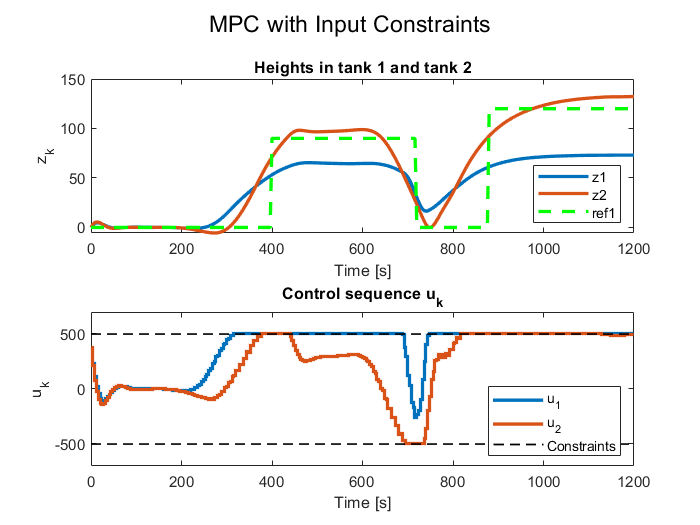

figure;
sgtitle('MPC with Input Constraints');
subplot(2,1,1)
plot(t',zbar_model',"LineWidth",2); hold on;
plot(t',ref(1:Nsim,1),'--','color','green',"LineWidth",2);
title('Heights in tank 1 and tank 2'); legend('z1','z2','ref1','location','southeast')
xlim([0 1200]); xlabel('Time [s]'); ylabel('z_k')

subplot(2,1,2)
stairs(t',u_system',"LineWidth",2); hold on;
plot(t',-500*ones(length(t),1),'--','color','black',"LineWidth",1); hold on;
plot(t',500*ones(length(t),1),'--','color','black',"LineWidth",1);
ylim([-700 700]); title('Control sequence u_k'); xlabel('Time [s]'); ylabel('u_k')
legend('u_1','u_2','Constraints','location','southeast')